clear

addpath("matlab_functions\")

#### Read MFD data

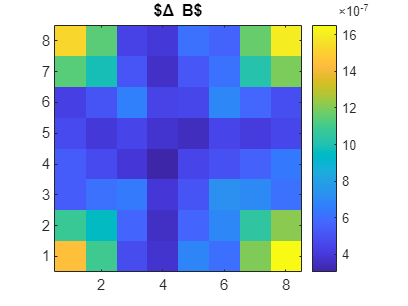

[B0,f1,defects] = readMFD('data/B_defectless.txt');
assert(isempty(defects))

[B,f2,defects] = readMFD('data/B_defect_circ2mm_throughhole.txt');

f = 1000; % Hz
delta_B = B(f2==f,:) - B0(f1==f,:);
delta_B = delta_B(:);

figure
imagesc(vecnorm(reshape(delta_B,8,8,[]), 2, 3).')
colorbar
title('$\Delta B$')
axis square xy


clear f1 f2 B0 B

#### Load $\Phi$

load('data\Phi.mat', 'Phi','freqs','voxels_center')

Phi = Phi(:,:,freqs==f);

xylim = 15e-3;
mask = -xylim < voxels_center(1,:) & voxels_center(1,:) < xylim & ...
       -xylim < voxels_center(2,:) & voxels_center(2,:) < xylim & ...
                                     voxels_center(3,:) > -3.1e-3;

Phi = Phi(:, mask, :);
voxels_center = voxels_center(:, mask);

y = delta_B;
% y = awgn(y, Inf, 'measured');

y = real(y);
Phi = real(Phi);

clear freqs delta_B xylim mask

#### Sum up all depths

xp = unique(voxels_center(1,:));
yp = unique(voxels_center(2,:));
[xp,yp] = ndgrid(xp,yp);

voxels_center_2D = [reshape(xp,1,[]); reshape(yp,1,[])];
Phi_2D = zeros(size(Phi,1), numel(xp));
for j = 1:numel(xp)
    mask = voxels_center(1,:) == voxels_center_2D(1,j) & voxels_center(2,:) == voxels_center_2D(2,j);
    Phi_2D(:,j) = sum(Phi(:,mask), 2);
end

voxels_center = voxels_center_2D;
Phi = Phi_2D;

clear xp yp voxels_center_2D Phi_2D j mask

#### Reconstruction

tic
z = pinv(Phi) * y;
fprintf("pinv uses %.2f seconds\n", toc)

pinv uses 0.01 seconds


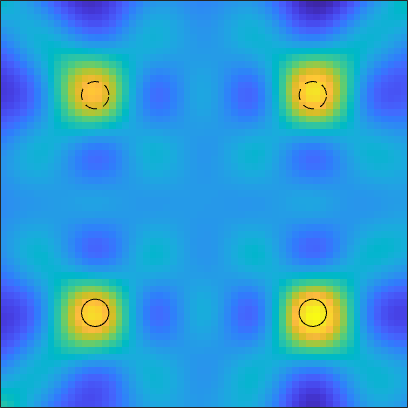

displayReconstruction(z, voxels_center, defects)


tic
lambda = 1e-3;
z = (Phi' * Phi + lambda * eye(size(Phi,2))) \ (Phi' * y);
fprintf("Tikhonov regularization uses %.2f seconds\n", toc)

Tikhonov regularization uses 0.21 seconds


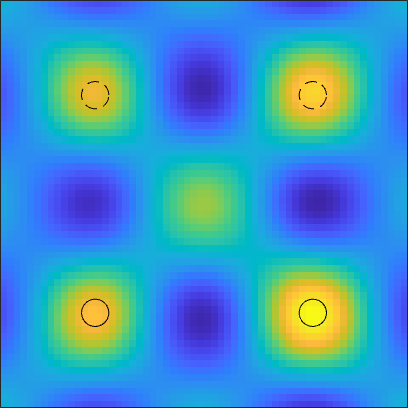

displayReconstruction(z, voxels_center, defects)


tic
lambda = 3.0e-13;
z = L1Regularize(Phi, y, lambda);
fprintf("L1 regularization uses %.2f seconds\n", toc)

L1 regularization uses 0.65 seconds


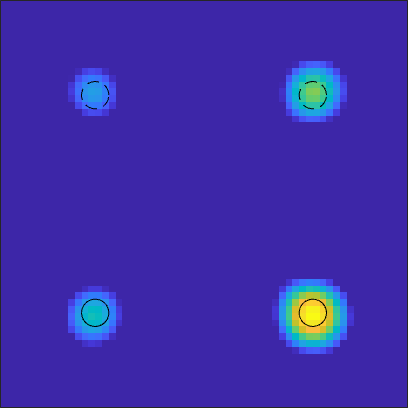

displayReconstruction(z, voxels_center, defects)


tic
z = SBL(Phi, y, 'MaxIterations',16);
fprintf("SBL uses %.2f seconds\n", toc)

SBL uses 1.06 seconds


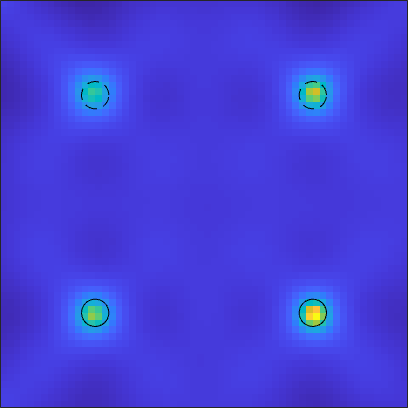

displayReconstruction(z, voxels_center, defects)


clear lambda reg

function [B, freqs, defects] = readMFD(fname)

B = [];
freqs = [];
defects = {};

lines = readlines(fname);

for k = 1:length(lines)
    str = strtrim(lines(k));
    str = convertStringsToChars(str);
    if isempty(str)
        continue
    end

    if ~startsWith(str, '%')
        B(end+1,:) = str2num(str);
    else
        str = strtrim(str(2:end));
        if startsWith(str, 'frequency')
            tokens = split(str);
            freqs(end+1) = str2num(tokens{2});
            assert(strcmp(tokens{3}, "Hz"))
        elseif startsWith(str, 'defect')
            i = strfind(str, ' ');
            defects{end+1} = jsondecode(str(i:end));
        else
            error('Unknown "%s"', str)
        end
    end
end

end

function displayReconstruction(c, voxels_center, defects)

for k = 1:1
    mask = ones(1,length(c),"logical");
    c_layer = reshape(c(mask), sqrt(sum(mask)),[]);

    x = [min(voxels_center(1,mask)) max(voxels_center(1,mask))];
    y = [min(voxels_center(2,mask)) max(voxels_center(2,mask))];
    dx = (x(2) - x(1)) / size(c_layer,1);
    dy = (y(2) - y(1)) / size(c_layer,2);

    figure('Position',[100 100 600 600])
    tiledlayout(1,1, 'TileSpacing','none', 'Padding','none')
    nexttile

    imagesc(x, y, c_layer.')
    axis square xy
    xticks([])
    yticks([])
    xlim(x + [-dx dx]/2)
    ylim(y + [-dy dy]/2)
    box on

    hold on
    for p = 1:length(defects)
        defect = defects{p};
        if max(defect.z1, defect.z2) < -1e-5
            linestyle = '--';
        else
            linestyle = '-';
        end
        plot_shape(defect, linestyle)
    end
end

end

function plot_shape(defect, linestyle)

if nargin < 2
    linestyle = "-";
end

switch lower(defect.type)
    case 'rectangular'
        rect = [defect.c_x-defect.dx/2 defect.c_y-defect.dy/2 defect.dx defect.dy];
        rectangle('Position', rect, 'LineStyle',linestyle)
    case 'circular'
        theta = linspace(0, 2*pi);
        x = defect.c_x + defect.d/2 * cos(theta);
        y = defect.c_y + defect.d/2 * sin(theta);
        plot(x, y, 'k', 'LineStyle',linestyle)
    case 'polygonal'
        plot(defect.xs, defect.ys, 'k', 'LineStyle',linestyle)
    otherwise
        error('Unknown defect shape "%s"', defect.type)
end

end